# Lecture 3: Equilibrium Points & Linearization

- Find the kinetic energy fo the system $T$.

- Find the potential energy of the system $V$. 

- Find the equilibrium points $q_{0\;}$.

- Classify the stability of the equilibrium points

- Find the linearized equations of motion about equilibrium

Welcome! A spring mass damper system on an incline is connected to a massless rod with a point mass at the end. Choose the generalized coordinates $q=\left\lbrack \begin{array}{c}
x\;\\
\theta \;\;
\end{array}\right\rbrack$.

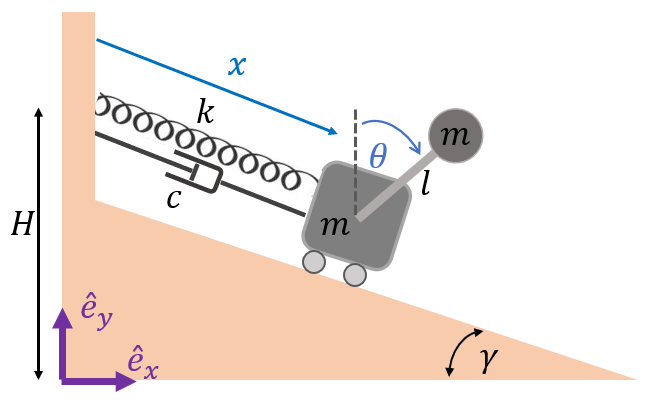

Assume the following properties:

- $l$ = 3                [m]

- $m$ = 5               [kg]

- $g$ = 9.81           [m/$s^{2\;}$]

- $\gamma \;$ = $\pi \;/6$           [rad]

- $H$ = 30              [m]

- $k=5$               [N/m]

- $l_0$ = 0                [m]

- $c=0\ldotp 4$            [Ns/m]

## Kinetic Energy

The kinetic energy of each object is calculated using the formula below. Since there are only point masses in the system $J_G =0$. 


$$T=\frac{1}{2}m{\dot{r_G } }^{T\;} \dot{r_G } +\frac{1}{2}J_G \omega {\;}^2$$



$$T=\frac{1}{2}m{\dot{r_G } }^{T\;} \dot{r_G }$$


clc; clear all; close all;
load("C:\Users\franc\OneDrive\Bureaublad\codespace\Githubcode\college\Dyn and Cont\deliverable 1\MeasuredSignals.mat")
syms L_0 L_1 L_2 m_0 m_1 m_2 m_3 d_x d_w d_phi d_theta k_theta g 
syms theta_ref k_x L_x theta theta_dot theta_ddot x x_dot x_ddot
syms phi(t) phi_dot M psi F_A 


%constants
g = 9.81;
L_0 = 30;
L_1 = 25;
L_2 = 10;
m_0 = 10^4;
m_1 = 10^4;
m_2 = 2000;
m_3 = 500;
d_x = 200;
d_w = 2000;
d_phi = 2;
k_theta = 200;
theta_ref = 0;
d_theta = 10;
k_x = 7000;
L_x = 12.5;


% Generalized Coordinates
q = [x;
    theta];
q_dot = [x_dot;
    theta_dot];
q_ddot = [x_ddot;
    theta_ddot];

% Position vectors
r_2 = [x*cos(phi(t));
      L_0 + x*sin(phi(t))];

r_3 = [x*cos(phi(t)) - L_2*cos(theta);
      L_0 + x*sin(phi(t)) - L_2*sin(theta)];

r_4 = [L_1*cos(phi(t));
      L_0 + L_1*sin(phi(t))];

% Velocity vectors
r_dot_2 = jacobian(r_2, q)*q_dot + jacobian(r_2, t);
r_dot_3 = jacobian(r_3, q)*q_dot + jacobian(r_3, t);
r_dot_4 = jacobian(r_4, q)*q_dot + jacobian(r_4, t);

% Kinetic Energy
T_2 = 1/2*m_2*transpose(r_dot_2)*r_dot_2;
T_2 = simplify(T_2, 'steps', 25)

$$T\_2 = 1000\,x^{2}\,{\left(\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}+1000\,{\dot{x}}^{2}$$

T_3 = 1/2*m_3*transpose(r_dot_3)*r_dot_3;
T_3 = simplify(T_3, 'steps', 25)

$$T\_3 = 250\,x^{2}\,{\left(\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}-5000\,\cos\left(\theta -\varphi \left(t\right)\right)\,\dot{\theta }\,x\,\frac{\partial }{\partial t}\varphi \left(t\right)+25000\,{\dot{\theta }}^{2}+5000\,\sin\left(\theta -\varphi \left(t\right)\right)\,\dot{\theta }\,\dot{x}+250\,{\dot{x}}^{2}$$

T_4 = 1/2*m_1*transpose(r_dot_4)*r_dot_4;
T_4 = simplify(T_4, 'steps', 25)

$$T\_4 = 3125000\,{\left(\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}$$

T = T_2 + T_3 + T_4;
T = simplify(T, 'steps', 25)

$$T = 1250\,x^{2}\,{\left(\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}+3125000\,{\left(\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}-5000\,\cos\left(\theta -\varphi \left(t\right)\right)\,\dot{\theta }\,x\,\frac{\partial }{\partial t}\varphi \left(t\right)+25000\,{\dot{\theta }}^{2}+5000\,\sin\left(\theta -\varphi \left(t\right)\right)\,\dot{\theta }\,\dot{x}+1250\,{\dot{x}}^{2}$$

## Potential Energy

The potential energy for the spring is given by the formula below. Neglect unstretched length ($l_{0\;} =0$).


$$V_k =\frac{1}{2}{k\left(x-l_{0\;} \right)}^{2\;}$$


The gravitational potential energy of each mass is calculated using the formula below. $y$ is the vertical height from the reference frame.


$$V_g =\textrm{mgy}$$


            % Gravitational potential energy
            V_1 = m_0*g*L_0/2

V_1 = 1471500

            V_2 = m_2*g*(L_0 + x*sin(phi(t)))

$$V\_2 = 19620\,x\,\sin\left(\varphi \left(t\right)\right)+588600$$

            V_3 = m_3*g*(L_0 + x*sin(phi(t)) - L_2*sin(theta))

$$V\_3 = 4905\,x\,\sin\left(\varphi \left(t\right)\right)-49050\,\sin\left(\theta \right)+147150$$

            V_4 = m_1*g*(L_0 + L_1/2*sin(phi(t)))

$$V\_4 = 1226250\,\sin\left(\varphi \left(t\right)\right)+2943000$$

            
            % Elastic potential energy
            V_k_1 = 1/2*k_x*(x - L_x)^2

$$V\_k\_1 = 3500\,{\left(x-\frac{25}{2}\right)}^{2}$$

            V_k_2 = 1/2*k_theta*((theta - phi) - theta_ref)^2

$$V\_k\_2(t) = 100\,{\left(\theta -\varphi \left(t\right)\right)}^{2}$$

            
            % combined
            V = (V_1 + V_2 + V_3 + V_4) + (V_k_1 + V_k_2)

$$V(t) = 1226250\,\sin\left(\varphi \left(t\right)\right)-49050\,\sin\left(\theta \right)+24525\,x\,\sin\left(\varphi \left(t\right)\right)+3500\,{\left(x-\frac{25}{2}\right)}^{2}+100\,{\left(\theta -\varphi \left(t\right)\right)}^{2}+5150250$$

            V = simplify(V)

$$V(t) = 1226250\,\sin\left(\varphi \left(t\right)\right)-49050\,\sin\left(\theta \right)+24525\,x\,\sin\left(\varphi \left(t\right)\right)+3500\,{\left(x-\frac{25}{2}\right)}^{2}+100\,{\left(\theta -\varphi \left(t\right)\right)}^{2}+5150250$$

## Generalized non-conservative force vector

First identify the non conservative forces $F_i$, and moments $M_j$. Then find the absolute position vectors $r_{i\;}$to where the forces are applied and the absolute rotation vectors $\theta_j$ to where the moments are applied. In this case, there the only non conservative forces are from the damper. The damper force against the wall will do no work (the wall isn't moving) so we can neglect it. However, the force due to the damper acting against the mass needs to be accounted for.


$$Q^{\textrm{nc}} =\sum_{i=1}^{n_F } {\left(r_{i,q} \right)}^T F_i +\sum_{j=1}^{n_M } {\left(\theta {\;}_{j,q} \right)}^T M_j$$



$$Q^{\textrm{nc}} ={\left(r_q \right)}^T F_{\;}$$


% Damper force vector
F_dx = [-d_x*x_dot*cos(phi(t));
       -d_x*x_dot*sin(phi(t))]

$$F\_dx = \left(\begin{array}{c} -200\,\dot{x}\,\cos\left(\varphi \left(t\right)\right)\\ -200\,\dot{x}\,\sin\left(\varphi \left(t\right)\right) \end{array}\right)$$


Q_nc_dx = transpose(jacobian(r_2, q))*F_dx;

psi = [0;
      0;
      theta - phi(t)];

M = [0;
    0;
    -d_theta*(theta_dot - phi_dot)]

$$M = \left(\begin{array}{c} 0\\ 0\\ 10\,\dot{\varphi }-10\,\dot{\theta } \end{array}\right)$$


Q_nc_dtheta = transpose(jacobian(psi, q))*M;

F_W = [-d_w*theta_dot*sin(theta);
      d_w*theta_dot*cos(theta)];

Q_nc_FW = transpose(jacobian(r_3, q))*F_W;

F_A = [F_A*cos(phi(t));
      F_A*sin(phi(t))];

Q_nc_FA = transpose(jacobian(r_2, q))*F_A;

Q_nc_dx = simplify(Q_nc_dx)

$$Q\_nc\_dx = \left(\begin{array}{c} -200\,\dot{x}\\ 0 \end{array}\right)$$

Q_nc_dtheta = simplify(Q_nc_dtheta)

$$Q\_nc\_dtheta = \left(\begin{array}{c} 0\\ 10\,\dot{\varphi }-10\,\dot{\theta } \end{array}\right)$$

Q_nc_FW = simplify(Q_nc_FW)

$$Q\_nc\_FW = \left(\begin{array}{c} -2000\,\dot{\theta }\,\sin\left(\theta -\varphi \left(t\right)\right)\\ -20000\,\dot{\theta } \end{array}\right)$$

Q_nc_FA = simplify(Q_nc_FA)

$$Q\_nc\_FA = \left(\begin{array}{c} F_{A}\\ 0 \end{array}\right)$$


Q_nc = Q_nc_dx + Q_nc_dtheta + Q_nc_FW + Q_nc_FA;
Q_nc = simplify(Q_nc)

$$Q\_nc = \left(\begin{array}{c} F_{A}-200\,\dot{x}-2000\,\dot{\theta }\,\sin\left(\theta -\varphi \left(t\right)\right)\\ 10\,\dot{\varphi }-20010\,\dot{\theta } \end{array}\right)$$

## Lagrange Equations of Motion

The equations of motion for each of the generalized coordinates can be found from


$$\frac{d}{\textrm{dt}}\left(T,_{\dot{q} } \right)-T,_q +V,_q ={\left(Q^{\textrm{nc}} \right)}^T$$


Note that the first term can be found from the chain rule. 


$$\frac{d}{\textrm{dt}}\left(T,_{\dot{q} } \right)={\left(\frac{\partial {\left(T_{,\dot{q} } \right)}^T }{\partial \;q}\dot{q} +\frac{\partial {\left(T,_{\dot{q} } \right)}^T }{\partial \;\dot{q} }\ddot{q} +\frac{\partial {\left(T,_{\dot{q} } \right)}^T }{\partial \;s}\dot{s} +\frac{\partial {\left(T,_{\dot{q} } \right)}^T }{\partial \;\dot{s} }\ddot{s} \right)}^T$$


But since there are no prescribed displacements ($s=0$) then


$$\frac{d}{\textrm{dt}}\left(T,_{\dot{q} } \right)={\left(\frac{\partial {\left(T_{,\dot{q} } \right)}^T }{\partial \;q}\dot{q} +\frac{\partial {\left(T,_{\dot{q} } \right)}^T }{\partial \;\dot{q} }\ddot{q} \right)}^T$$


% First term
dTdq_dot = jacobian(T, q_dot);
First_Term = jacobian(transpose(dTdq_dot),q)*q_dot + jacobian(transpose(dTdq_dot),q_dot)*q_ddot;
First_Term = transpose(First_Term);
First_Term = simplify(First_Term)

$$First\_Term = \begin{array}{l} \left(\begin{array}{cc} 5000\,\sigma_{2}\,{\dot{\theta }}^{2}+2500\,\ddot{x}+5000\,\ddot{\theta }\,\sigma_{1} & 50000\,\ddot{\theta }+5000\,\ddot{x}\,\sigma_{1}+\dot{\theta }\,\left(5000\,\dot{x}\,\sigma_{2}+5000\,x\,\sigma_{1}\,\frac{\partial }{\partial t}\varphi \left(t\right)\right)-5000\,\dot{x}\,\sigma_{2}\,\frac{\partial }{\partial t}\varphi \left(t\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta -\varphi \left(t\right)\right)\\ \sigma_{2}=\cos\left(\theta -\varphi \left(t\right)\right) \end{array}$$


% Second term
Second_Term = jacobian(T, q);
Second_Term = simplify(Second_Term)

$$Second\_Term = \left(\begin{array}{cc} 2500\,x\,{\left(\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}-5000\,\dot{\theta }\,\cos\left(\theta -\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right) & 5000\,\dot{\theta }\,x\,\sin\left(\theta -\varphi \left(t\right)\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)+5000\,\dot{\theta }\,\dot{x}\,\cos\left(\theta -\varphi \left(t\right)\right) \end{array}\right)$$


% Third term
Third_Term = jacobian(V, q);
Third_Term = simplify(Third_Term)

$$Third\_Term(t) = \left(\begin{array}{cc} 7000\,x+24525\,\sin\left(\varphi \left(t\right)\right)-87500 & 200\,\theta -49050\,\cos\left(\theta \right)-200\,\varphi \left(t\right) \end{array}\right)$$


% Equations of Motion
EoM = First_Term + Second_Term + Third_Term == transpose(Q_nc);
EoM = simplify(EoM);
EoM = transpose(EoM)

$$EoM(t) = \begin{array}{l} \left(\begin{array}{c} 2500\,x\,{\left(\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}+5000\,\sigma_{2}\,{\dot{\theta }}^{2}+2000\,\sigma_{1}\,\dot{\theta }+7000\,x+200\,\dot{x}+2500\,\ddot{x}+24525\,\sin\left(\varphi \left(t\right)\right)+5000\,\ddot{\theta }\,\sigma_{1}=5000\,\dot{\theta }\,\sigma_{2}\,\frac{\partial }{\partial t}\varphi \left(t\right)+F_{A}+87500\\ 500\,\dot{x}\,\sigma_{2}\,\frac{\partial }{\partial t}\varphi \left(t\right)+\dot{\varphi }+4905\,\cos\left(\theta \right)+20\,\varphi \left(t\right)=1000\,\dot{\theta }\,x\,\sigma_{1}\,\frac{\partial }{\partial t}\varphi \left(t\right)+20\,\theta +2001\,\dot{\theta }+5000\,\ddot{\theta }+500\,\ddot{x}\,\sigma_{1}+1000\,\dot{\theta }\,\dot{x}\,\sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta -\varphi \left(t\right)\right)\\ \sigma_{2}=\cos\left(\theta -\varphi \left(t\right)\right) \end{array}$$

## Equilibrium Points

Solve for equilibrium Points by finding the stationary points of the potential energy


$${\left(V_{,q} \right)}^T =0$$


The MATLAB solve() and vpasolve() functions are pretty bad (in my opinion) so I'd usually recommend solving by hand or using Mathematica.

syms x theta real

% Define phi = 0
phi = 0;

% Substitute phi=0 into V
V = 1226250*sin(phi)- 49050*sin(theta) ...
    + 24525*x*sin(phi) ...
    + 3500*(x - 25/2)^2 ...
    + 100*(theta - phi)^2 ...
    + 5150250;

V = simplify(V);

% Compute gradient
dVdq = jacobian(V, [x; theta]).';

% Solve for equilibrium
sol = vpasolve( [dVdq(1) == 0, dVdq(2) == 0], ...
                [x, theta], ...
                [12.5, pi/2] );

x_0 = double(sol.x);
theta_0 = double(sol.theta);

q_0 = [x_0; theta_0]

q_0 =    12.5000
    1.5644


Find if the equilibrium point is stable or not. $q_0$ is stable if the hessian of $V$ is positive definite:


$${\left(V_{,q} \right)}_{,q\;|q=q_{0,} \dot{q} =0}^T \succ 0$$


For simplicity, we'll treat any other result as unstable. There are many ways to show if a matrix is positive definite. One way is to find the eigenvalues of the matrix, and if all the eigenvalues are positive then the matrix is positive definite. 

% Find hessian and sub in equilibrium point
dVdq2 = hessian(V,q);
dVdq2 = simplify(dVdq2);
dVdq2 = subs(dVdq2,q,q_0); % sub in q0

% Determine if positive definite
eig_val = eig(dVdq2);
isposdef = all(eig_val > 0) % if =1 then stable.

isposdef = logical
   1


## Linearization

We've found that one stable equilibrium point is $q_0 =\left\lbrack \begin{array}{c}
\frac{2\textrm{mg}}{k}\sin \left(\gamma \right)\\
\pi \;
\end{array}\right\rbrack$. We can approximate the equations of motion near this equilibrium point using the substitution: 


$${q\left(t\right)=q_0 +q}_1 \left(t\right)$$



$${\dot{q} \left(t\right)=\dot{q} }_1 \left(t\right)$$



$${\ddot{q} \left(t\right)=\ddot{q} }_1 \left(t\right)$$


Where the term $q_1$ is a *small* displacement from the equilibrium. The approximate linear Equation of Motion near this fixed point can be found using this formula:


$$M_0 \ddot{q_1 } +D_0 \dot{q_1 } +\left(K_0 +K_0^Q \right)q_1 =Q\left(t\right)$$


Mass Matrix:                                             $M_0 ={\left(T_{,\dot{q} } \right)}_{,\dot{q} \;|q=q_{0,} \dot{q} =0}^T$

Damping Matrix:                                       $D_0 =-{Q^{\textrm{nc}} }_{,\dot{q} \;|q=q_{0,} \dot{q} =0}$

Stiffness Matrix:                                       $K_0 ={\left(V_{,q} \right)}_{,q\;|q=q_{0,} \dot{q} =0}^T$

Non Conservative Stiffness Matrix:         $K_0^Q =-{Q^{\textrm{nc}} }_{,q|q=q_{0,} \dot{q} =0}$

Force Vector:                                           $Q\left(t\right)={Q^{\textrm{nc}} }_{|q=q_{0,} \dot{q} =0}$

M_0 = hessian(T,q_dot);
M_0 = subs(M_0,q,q_0); %sub in q = q_0
M_0 = subs(M_0,q_dot,[0;0]) % sub in q_dot = 0

$$M\_0 = \left(\begin{array}{cc} 2500 & -5000\,\sin\left(\varphi \left(t\right)-\frac{7045509688949645}{4503599627370496}\right)\\ -5000\,\sin\left(\varphi \left(t\right)-\frac{7045509688949645}{4503599627370496}\right) & 50000 \end{array}\right)$$


D_0 = jacobian(-Q_nc,q_dot);
D_0 = subs(D_0,q,q_0);
D_0 = subs(D_0,q_dot,[0;0])

$$D\_0 = \left(\begin{array}{cc} 200 & -2000\,\sin\left(\varphi \left(t\right)-\frac{7045509688949645}{4503599627370496}\right)\\ 0 & 20010 \end{array}\right)$$


K_0 = hessian(V,q);
K_0 = subs(K_0,q,q_0);
K_0 = subs(K_0,q_dot,[0;0])

$$K\_0 = \left(\begin{array}{cc} 7000 & 0\\ 0 & 49050\,\sin\left(\frac{7045509688949645}{4503599627370496}\right)+200 \end{array}\right)$$


K_0_Q = jacobian(-Q_nc,q);
K_0_Q = subs(K_0_Q,q,q_0);
K_0_Q = subs(K_0_Q,q_dot,[0;0])

$$K\_0\_Q = \left(\begin{array}{cc} 0 & 0\\ 0 & 0 \end{array}\right)$$


Q = subs(Q_nc,q,q_0);
Q = subs(Q,q_dot,[0;0])

$$Q = \left(\begin{array}{c} F_{A}\\ 10\,\dot{\varphi } \end{array}\right)$$


EoM_linearized = M_0*q_ddot + D_0*q_dot + (K_0+K_0_Q)*(q-q_0) == Q

$$EoM\_linearized = \begin{array}{l} \left(\begin{array}{c} 7000\,x+200\,\dot{x}+2500\,\ddot{x}-2000\,\dot{\theta }\,\sigma_{1}-5000\,\ddot{\theta }\,\sigma_{1}-87500=F_{A}\\ 20010\,\dot{\theta }+50000\,\ddot{\theta }-5000\,\ddot{x}\,\sigma_{1}+\left(\theta -\frac{7045509688949645}{4503599627370496}\right)\,\left(49050\,\sin\left(\frac{7045509688949645}{4503599627370496}\right)+200\right)=10\,\dot{\varphi } \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\varphi \left(t\right)-\frac{7045509688949645}{4503599627370496}\right) \end{array}$$


F = Q - D_0*q_dot - (K_0 + K_0_Q)*(q - q_0)

$$F = \left(\begin{array}{c} F_{A}-7000\,x-200\,\dot{x}+2000\,\dot{\theta }\,\sin\left(\varphi \left(t\right)-\frac{7045509688949645}{4503599627370496}\right)+87500\\ 10\,\dot{\varphi }-20010\,\dot{\theta }-\left(\theta -\frac{7045509688949645}{4503599627370496}\right)\,\left(49050\,\sin\left(\frac{7045509688949645}{4503599627370496}\right)+200\right) \end{array}\right)$$

M = M_0

$$M = \left(\begin{array}{cc} 2500 & -5000\,\sin\left(\varphi \left(t\right)-\frac{7045509688949645}{4503599627370496}\right)\\ -5000\,\sin\left(\varphi \left(t\right)-\frac{7045509688949645}{4503599627370496}\right) & 50000 \end{array}\right)$$

## Simulation

*(don't worry if you don't understand the code below. A separate video & example will be provided showing you how to implement this easily in Simulink)*

One way to solve this is to put the equation of motion in state space form (beyond scope of this course) & to simulate it using ODE45.

%{
syms x(t) theta(t)
t_interval = [0,20];
y_IC = [q_0(1)+4, 0, q_0(2)+0.3, 0]; % Initial position & Initial velocity (in state space form)
    % y1 = x
    % y2 = d/dt x
    % y3 = theta
    % y4 = d/dt theta
S_desired = ["x"; "Dx"; "theta"; "Dtheta"]; % elements of state

%% Nonlinear EoM simulation calcs
EoM = subs(EoM, {'x', 'theta', 'x_dot', 'theta_dot', 'x_ddot', 'theta_ddot'}, [x(t) theta(t), diff(x,t), diff(theta,t), diff(x,t,2), diff(theta,t,2)]);
EoM = formula(EoM);
[F, S] = odeToVectorField(EoM(1),EoM(2));
S = string(S);
for i = 1:length(S_desired)
    index(i) = find(S == S_desired(i));
end
V_fun = matlabFunction(F,'vars',{'t','Y'});
y_IC = y_IC(index);
[t_sol,y_sol] = ode45(V_fun,t_interval,y_IC);
y_sol = y_sol(:,index);
x_sol = y_sol(:,1);
theta_sol = y_sol(:,3);

%% Linear EoM Simulations calcs
EoM_linearized = subs(EoM_linearized, {'x', 'theta', 'x_dot', 'theta_dot', 'x_ddot', 'theta_ddot'}, [x(t) theta(t), diff(x,t), diff(theta,t), diff(x,t,2), diff(theta,t,2)]);
EoM_linearized = formula(EoM_linearized);
[F, S] = odeToVectorField(EoM_linearized(1),EoM_linearized(2));
S = string(S);
for i = 1:length(S_desired)
    index(i) = find(S == S_desired(i));
end
V_fun = matlabFunction(F,'vars',{'t','Y'});
[t_linear_sol,y_sol] = ode45(V_fun,t_interval,y_IC);
y_sol = y_sol(:,index);
x_linear_sol = y_sol(:,1);
theta_linear_sol = y_sol(:,3);

% Plot
plot(t_sol,x_sol,'r','LineWidth',2,'DisplayName','x [m]')
hold on
plot(t_linear_sol,x_linear_sol,'b--','LineWidth',2,'DisplayName','x_{linearized} [m]')
hold off
xlabel('t [seconds]')
legend()
title('Nonlinear EoM vs Linear EoM')
subtitle('x(t)')

plot(t_sol,theta_sol,'r','LineWidth',2,'DisplayName','\theta [rad]')
hold on
plot(t_linear_sol,theta_linear_sol,'b--','LineWidth',2,'DisplayName','\theta_{linearized} [rad]')
xlabel('t [seconds]')
title('Nonlinear EoM vs Linear EoM')
subtitle('\theta(t)')
legend()
%}


